# INVASIVE MODAL CONTROL (SELF TUNING)

a_model_setup

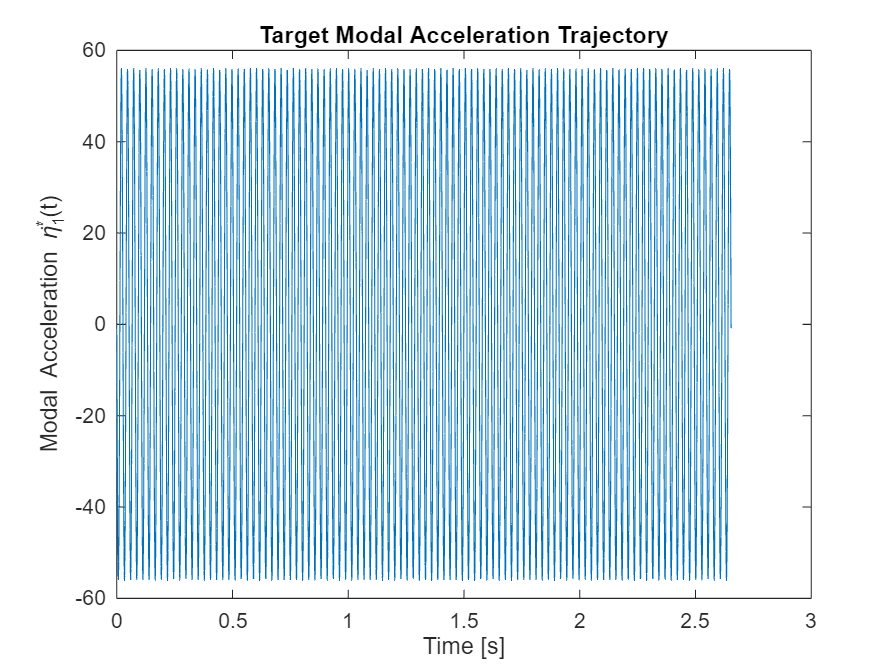

% Time and sampling
Ts = 1/1000;
num_periods = 100;
T_total = ceil((num_periods*2*pi/model.omega)/Ts)*Ts; % used to ensure at least num_periods are simulated
t_vec = 0:Ts:T_total;
t_num = length(t_vec);

% Initial state: [eta1, eta2, eta_dot1, eta_dot2, I, psi]
x0 = zeros(5,1);

% Store history
t_all = t_vec';
x_all = zeros(t_num, 5);
v_all = zeros(t_num, 1);
a_all = zeros(t_num, 2);
eta_e1_prev = 0;


% % Control gains
% model.k1 = 1;
% model.k2 = 0.1;
% model.Ts = Ts;
% psi = 0.1;
% psi_lim = 0.11;
% a_all(1) = psi;

% Control gains
model.k1 = 1.49;
model.k2 = 1e-2;
model.Ts = Ts;
psi_init = 0.001;
psi_lim = 0.3;
psi_rate_lim = 0.3;
a_all(1) = psi_init;

% Desired trajectory
target_amp = 1e-3;
% Set A and B target harmonics
A_vec_target = zeros(model.harmonics, 1);
B_vec_target = zeros(model.harmonics, 1);
B_vec_target(1) = target_amp;  % fundamental sine term

% Precompute harmonic frequencies
harmonics = (1:model.harmonics)';
omega_h = model.omega * harmonics;  % [harmonics x 1]

% Define eta_star(t) and eta_ddot_star(t)
model.eta_star = @(t) A_vec_target.' * cos(omega_h * t) + B_vec_target.' * sin(omega_h * t);
model.eta_ddot_star = @(t) - (A_vec_target .* omega_h.^2).' * cos(omega_h * t) ...
                          - (B_vec_target .* omega_h.^2).' * sin(omega_h * t);

% Plot eta_ddot_star
figure;
plot(t_all, arrayfun(model.eta_ddot_star, t_all))
xlabel('Time [s]')
ylabel('Modal Acceleration \etä^*_1(t)')
title('Target Modal Acceleration Trajectory')

amp_err = 1.0168

amp_err = 1.0147

amp_err = 1.0128

amp_err = 1.0111

amp_err = 1.0097

ans = "within tolerance > model.k1 = 1.4983"

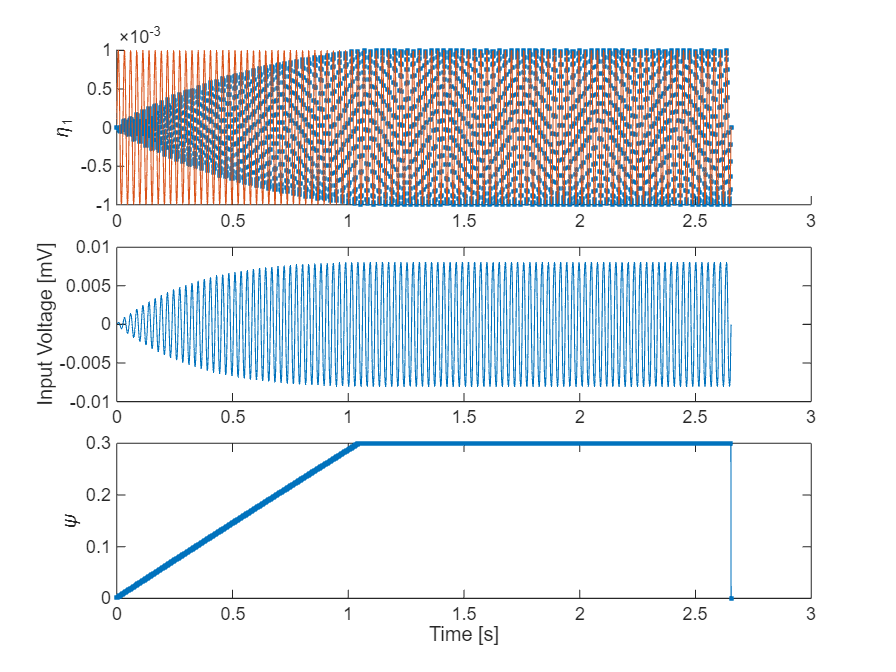

a_gain_shaping

ans =    -1.7818   -8.3280
    0.0103    0.0613
   -0.4815   -0.3256


residual_err = 0.0686

ans =    -2.7349   -8.0980
    0.0356    0.0382
   -0.0267   -0.6174


residual_err = 0.0726

ans =    -2.7177   -8.0529
    0.0694    0.0391
    0.7546   -0.3985


residual_err = 0.1008

ans =    -1.7741   -8.2206
    0.1176    0.1056
    0.6178    0.9697


residual_err = 0.1380

ans =     6.0015   -0.7521
    0.3346    0.0528
   -0.4423   -0.9302


residual_err = 0.1793

ans =    -5.6295    1.9374
    1.4289   -2.3375
   -4.7498  -12.3515


residual_err = 2.2699

ans =   -32.1110 -107.9528
    9.2194   15.1605
   30.2895   13.9620


residual_err = 0.3354

ans =   -34.3817 -107.8301
    9.3677   14.9850
   30.9470   12.5961


residual_err = 0.3340

ans =   -80.4273  -93.7961
    4.1031    2.7189
   25.6755  -29.9236


residual_err = 0.3216

ans =   -67.9108 -100.6776
    6.7289    5.2464
   32.2230  -17.8361


residual_err = 0.3113

ans =   -97.0560   51.7975
  -14.1594    7.8442
  -11.6064  -31.0668


residual_err = 0.3354

ans =   -96.6967   53.4894
  -13.1105    8.3407
  -12.7629  -31.7399


residual_err = 0.3400

ans =   -96.0026   54.9503
  -12.0027    8.9908
  -13.7076  -32.2224


residual_err = 0.3444

ans =   -63.1947 -107.3384
    6.9617    2.6413
   43.0904  -14.3634


residual_err = 0.3695

ans =   -65.5082 -106.8904
    7.0788    2.6341
   42.0139  -16.6484


residual_err = 0.3655

ans =   -67.5077 -106.4499
    7.2842    2.6628
   40.9782  -18.8576


residual_err = 0.3631

ans =   -94.2889   20.4237
  -18.0365   11.9974
   21.1633  -36.0637


residual_err = 0.4881

ans =   -27.1701   89.7652
    4.9948   22.2159
  -41.3087   34.8755


residual_err = 0.6255

ans =   -27.9977   91.2943
    4.5530   22.9786
  -39.2886   38.0354


residual_err = 0.6230

ans =   -78.2157   44.5100
  -14.1871   21.4361
   -8.4462  -38.2193


residual_err = 0.5203

ans =   -24.7738   91.8173
    4.9202   22.1168
  -38.6156   40.7671


residual_err = 0.6367

ans =   -24.3461   93.0405
    3.6534   22.9466
  -36.9573   43.2548


residual_err = 0.6390

ans =   -75.8173   48.4788
  -13.7314   20.9573
  -13.2191  -38.6573


residual_err = 0.5326

ans =   -64.6513   83.4642
  -10.3336   17.5295
  -51.8220   -9.5548


residual_err = 0.5350

ans =   -70.8302   51.9386
  -13.1171   19.7975
  -15.9370  -42.4072


residual_err = 0.5824

ans =   -67.4549   52.7940
  -11.1829   21.4498
  -16.9881  -47.8564


residual_err = 0.6567

ans =   -57.7875   39.8966
  -14.2321   -0.3276
   66.1237   18.7389


residual_err = 0.9995

ans =     7.7645  -83.7891
    2.7038   22.5599
   -3.9990  -39.5100


residual_err = 0.5437

ans =     7.4374  -83.8856
    3.5437   22.0765
   -4.6087  -39.4402


residual_err = 0.5411

ans =    23.7434  -88.5880
    1.2728   53.7388
   16.0804  -39.9674


residual_err = 0.7511

ans =    54.7245  -47.3724
    2.2633   25.0088
   21.9191   21.7302


residual_err = 0.5497

ans =   -37.4589   87.0260
    4.9297   22.1327
  -52.6651   33.0370


residual_err = 0.6985

ans =   -18.2085   89.8876
    3.8148   19.7914
  -37.6708   54.5874


residual_err = 0.7558

ans =   -23.1825   83.4995
    7.4903   20.6351
  -42.6120   39.3161


residual_err = 0.7154

ans =   -25.0416  -84.9189
   -2.2723   20.8875
  -49.4686  -10.7243


residual_err = 0.6190

ans =   -79.9301   41.0532
  -11.5211   17.1357
   -2.0947  -47.6008


residual_err = 0.5779

ans =   -45.1798  -82.9467
   34.1079   19.8045
   31.7426    0.0597


residual_err = 0.5360

ans =   -68.0227   53.0496
   -2.5810   23.4492
  -19.3462  -45.0789


residual_err = 0.6310

ans =   -35.8510  100.4804
   -1.6624   26.4397
    5.2098   65.3175


residual_err = 0.6625

ans =   -32.6378  -85.1278
   22.2816   56.1191
  -56.3866    5.7768


residual_err = 0.9084

ans =   -70.2739   47.8055
   -2.5530   25.2743
  -17.2641  -44.4806


residual_err = 0.6360

ans =   -14.9849  -82.6993
  -14.3374   39.7139
  -39.7145  -34.0818


residual_err = 0.8001

ans =   -62.5096   37.8205
   -3.8883  -38.3414
   -3.8883  -38.3414


residual_err = 0.7460

ans = "control_volt too high: 4508094942.8839"

ans = 1.0e+08 *

    1.9198   -0.4466
    2.0589   -1.2825
    1.5943   -2.6112


residual_err = 1.9808

ans =   -28.2535    3.8345
    5.4447    9.8160
   -0.6152  -81.5427


residual_err = 2.8869

ans = "control_volt too high: 2947724226.2913"

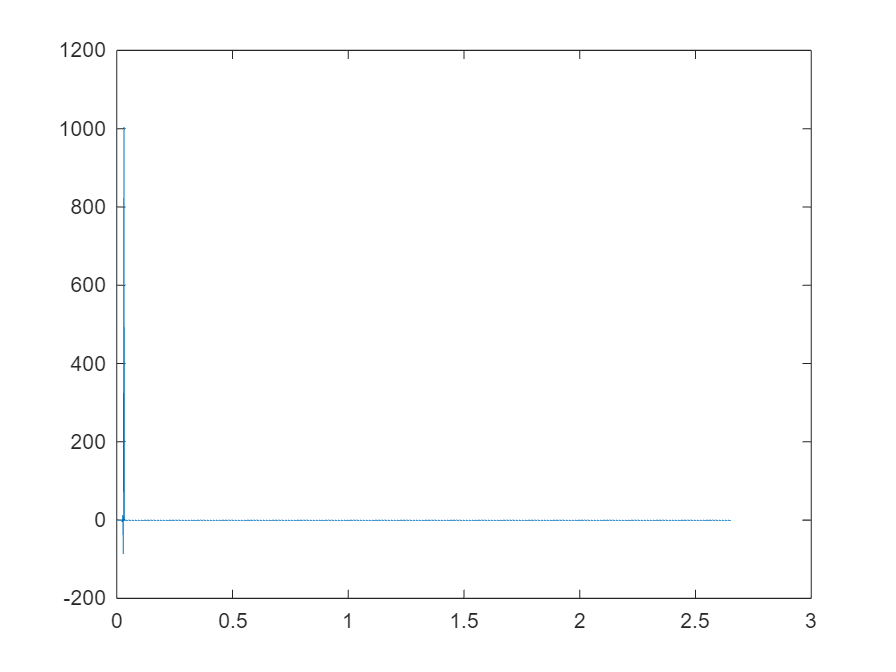

Error using f_get_last_n_periods (line 10)
Not enough zero crossings detected to extract 10 full periods.

for m = 1:50
    % Extract modal response over last N periods
    [t_lin, x_lin] = f_get_last_n_periods(t_all, x_all(:, 1), 10);  % modal disp
    [A_eta, B_eta] = f_get_fft_components(t_lin, x_lin, model.omega, model.harmonics);
    


    % Extract current signal
    % I_sig = x_all(:, 5);
    I_sig = v_all;
    [t_lin2, I_sig_crop] = f_get_last_n_periods(t_all, I_sig, 10);
    [A_I_sig, B_I_sig] = f_get_fft_components(t_lin2, I_sig_crop, model.omega, model.harmonics);
    [A_I_sig, B_I_sig]

    lambda = 0.1;
    n_factor = (B_vec_target(1)/B_I_sig(1, 1));
    A_vec_target(2:end) = A_vec_target(2:end) - lambda * A_I_sig(2:end,1).*n_factor;
    B_vec_target(2:end) = B_vec_target(2:end) - lambda * B_I_sig(2:end,1).*n_factor;
    residual_err = sqrt(sum([A_I_sig(2:end, 1), B_I_sig(2:end, 1)].^2, "all"))/sqrt(sum([A_I_sig(1, 1), B_I_sig(1, 1)].^2, "all"))
    

    % if residual_err > 1
    %     a_gain_shaping;
    % else
    if residual_err < 0.05
        break
    else
        a_inner_simulation;
    end
end

tiledlayout(2, 1, "TileSpacing","compact")
nexttile()
hold on;
plot(t_all, x_all(:, 1), ".-")
plot(t_all, arrayfun(model.eta_star,t_all))
ylabel("\eta_1")
title("Modal Response");
nexttile
plot(t_all, v_all./1000);
ylabel("Input Voltage [mV]");
title("Control Voltage")
